%% Lab Flux Test Set-Point Calculations
%
% Lincoln Scheer
% 25 April 2024
%
%
% The purpose of this script is to determine MFC set-points that will
% simulate expected flux ranges in the lab environment.

clc, clear, close all

%% System Assumptions

% Chamber Surface Area
As = 0.064844702; % [m^2]

% Environment Assumptions
P = 101325; % [Pa]
T = 293.15; % [K]

% Expected Flux Ranges
F_l = 0.5; % low range [umol/m^2/s]
F_h = 10; % high range [umol/m^2/s]

% Delivery Tank Concentration
Ctank = 400; % [ppm]

% MFC Size Used
MFC_q = 2.5; % [lpm]

% Resolution
res = 10;

% Unit Conversion Functions
ppm_to_mol = @(ppm) (ppm*P)/(1e6*8.314*T);  % ppm to mol/m^3
mol_to_ppm = @(mol) (1e6*8.314*mol*T)/P;    % mol/m^3 to ppm
lpm_to_cms = @(lpm) lpm/60000;              % liters per min to m^3 per min
cms_to_lpm = @(cms) cms*60000;              % m^3 per min to liters per min

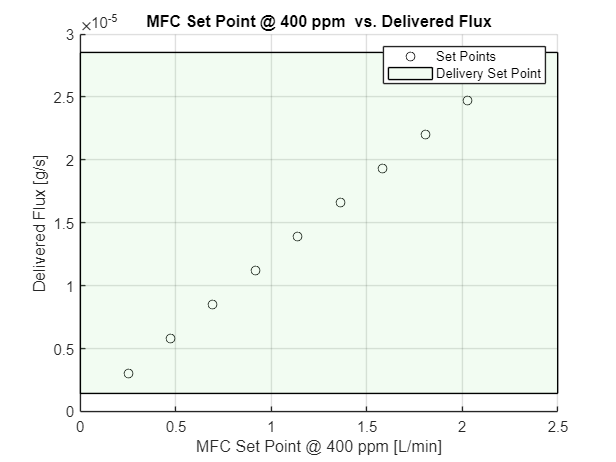

% Converting Flux Delivery from [umol/m^2/s] to [g/s]
w_F_l = F_l * 44.0095 * 1e-6 * As;
w_F_h = F_h * 44.0095 * 1e-6 * As; 

% Calculate Possible Setpoint Range % [m^3/s]
mfc_low = lpm_to_cms(MFC_q*0.1);
mfc_high = lpm_to_cms(MFC_q - MFC_q*0.1);
mfc_set_pt_rng = linspace(mfc_low, mfc_high, res);

% Convert Tank Concentration from [ppm] to [g/m^3]
w_Ctank = ppm_to_mol(Ctank)*44.0096;

% Calculate Possible Delivery Range [g/s]
dlv_set_pt_rng = mfc_set_pt_rng * w_Ctank;

% Plotting Set Points vs. Delivered Flux
%
%   Green shaded area indicates desired delivered fluxes that we want, if
%   delivery set points are outside of green range, adjust the Ctank
%   concentration delivered or the MFC size used.
%
figure()
hold on
plot(cms_to_lpm(mfc_set_pt_rng), dlv_set_pt_rng, 'ko')
patch([min(xlim) max(xlim) max(xlim) min(xlim)], [w_F_l w_F_l w_F_h, w_F_h], [0.5 0.9 0.5], 'FaceAlpha', 0.1)
title("MFC Set Point @ " + Ctank + " ppm  vs. Delivered Flux")
legend(["Set Points", "Delivery Set Point"])
xlabel("MFC Set Point @ " + Ctank + " ppm [L/min]")
ylabel("Delivered Flux [g/s]")
grid on

set_points = table(cms_to_lpm(mfc_set_pt_rng)', dlv_set_pt_rng', 'VariableNames', ["Set Point [LPM]", "Delivered Flux [g/s]"])

set_points = 10×2 table
    Set Point [LPM]    Delivered Flux [g/s]
    _______________    ____________________

           0.25             3.0494e-06     
        0.47222               5.76e-06     
        0.69444             8.4705e-06     
        0.91667             1.1181e-05     
         1.1389             1.3892e-05     
         1.3611             1.6602e-05     
         1.5833             1.9313e-05     
         1.8056             2.2023e-05     
         2.0278             2.4734e-05     
           2.25             2.7445e-05     


set_points.("Delivered Flux [g/day]") = (set_points.("Delivered Flux [g/s]")*60*60*24)/As

set_points = 10×3 table
    Set Point [LPM]    Delivered Flux [g/s]    Delivered Flux [g/day]
    _______________    ____________________    ______________________

           0.25             3.0494e-06                  4.063        
        0.47222               5.76e-06                 7.6746        
        0.69444             8.4705e-06                 11.286        
        0.91667             1.1181e-05                 14.898        
         1.1389             1.3892e-05                 18.509        
         1.3611             1.6602e-05                 22.121        
         1.5833             1.9313e-05                 25.733        
         1.8056             2.2023e-05                 29.344        
         2.0278             2.4734e-05                 32.956        
           2.25             2.7445e-05                 36.567        


load('q_calib.mat')

Error using load
'q_calib.mat' is not found in the current folder or on the MATLAB path, but exists in:
    A:\lincoln_scheer\git\co2_flux_summer_24\mfc_calibration

Change the MATLAB current folder or add its folder to the MATLAB path.

set_points.("Corrected Set Point [SLPM]") = predict(Q_actual, cms_to_lpm(mfc_set_pt_rng)')